# Loading, handling and subsetting the data

The set of data we will work on in this tutorial series consists in recordings performed in the hippocampus while rats run back and forth on a linear track to get a water reward. Additionally, the animal received an aversive air puff when crossing a certain position along the track and only in one running direction. 

The recording sessions were organized in 5 consecutive conditions: 1) in the "**pre-run**" condition, the animal was free to evolve on the linear track without receiving air puffs; 2) in the "**pre-sleep**" condition, the animal was brought to its home cage for sleep; 3) in the "**run**" condition, the animal was placed back on the track. Ths is the condition where it receives air puffs when crossing a particular position in a specific direction; 4) in the "**post-sleep**" condition, the animal was moved to its home cage again for another sleep period; 5) in the "**post-run**" condition, the animal was placed on the track again but received no aversive air-puff this time. 

Animals were recorded multiple days. Over successive days, the position and the direction for which the animal received an air puff during the "run" condition were changed pseudo-randomly. The data set we will work on consists in one recording session, in a specific animal.

The experimental procedure was developed by G. Girardeau, I. Inema and G. Buzsaki  (New York University Medical Center) . It was designed to investigate the neural correlates of the association between place and threat, both at the single and population levels.

In this first tutorial, the objective is to familiarize yourself with the data and the significance of the behavioral and electrohysiological variables that have been tracked, by visualizing the behavioral data across different conditions and plotting spikes in relation to that behavior.

In the meantime, you will learn how to : 

- subset the data to extract segments of interests; 

- resample different streams of data to ensure alignement and facilitate subsequent analysis;

- calculate event-triggered averages;

- compute 1D and 2D heat maps.

*Some useful peace of code incorporated in this tutorial are in the following functions: ****ComputeTriggeredAverage****, ****Compute1DMap****, ****GaussianSmooth1D****, ****Compute2DMap****.m and ****GaussianSmooth****.  At the end of this tutorial, you should know what the following functions do and how they do it.*

## **1. Import and pre-process behavioral data**

#### 1.1 Load parameters

*Define a set of parameters required to load the data. We will store these parameters in a matlab structure called loadparams.*

%Making sure the code is on Matlab path
addpath(genpath('/MATLAB Drive/Code'));

%animal name and session ID
loadparams.animalname = 'Rat08';
loadparams.session = 20130713;

%directory where data are stored
loadparams.Datafolder = ['/MATLAB Drive' filesep 'Dataset' filesep 'Session1'];

%Names of the .mat files to load
loadparams.posfilename = 'Positions.mat';
loadparams.laptypefilename = 'LapType2.mat';
loadparams.spkfilename = 'HippoSpikes.mat';
loadparams.spkinfofilename = 'IndexType.mat';

%Names of the event files to load
loadparams.catevtfilename = [loadparams.animalname '-' num2str(loadparams.session) '.cat.evt'];
loadparams.pufevtfilename = [loadparams.animalname '-' num2str(loadparams.session) '.puf.evt'];
loadparams.rrwevtfilename = [loadparams.animalname '-' num2str(loadparams.session) '.rrw.evt'];
loadparams.lrwevtfilename = [loadparams.animalname '-' num2str(loadparams.session) '.lrw.evt'];

%Size of the pixels of the video tracking in cm
loadparams.pix2cm = 0.43;

%Final smapling rate at which behavioral and spiking data will be resampled
loadparams.sampleRate = 50;

%List of shank numbers from which spikes will be loaded (corresponding to
%those located in the hippocampus)
loadparams.ShankList = 1:4;

*This default set of parameters related to loading the data can be obtained by calling DefineMapsParams.m*

loadparams = DefineLoadParams;

#### 1.2 Load the raw behavioral data

Load the position data, the timestamps for subsession limits, the type of laps, the airr puff and the rewards, using the information provided in loadparams. ".evt" files can be loaded with **LoadEvents.m**

%loading position data where timestamps, X and Y are in the first, second and
%third columns respectively
pos = load([loadparams.Datafolder filesep loadparams.posfilename]);

%loading subsessions indices (pre-run, run etc). 
%'timestamps' contains the start and end indices of each subsession;
% 'description' contains a txt descriptor of the type of subsession.
catevents = LoadEvents([loadparams.Datafolder filesep loadparams.catevtfilename]);

%Information about types of trial, i.e. whether the animal is going for
%the right platform or the left one.
LapType = load([loadparams.Datafolder filesep loadparams.laptypefilename]);

%air puffs timestamps
pufevents = LoadEvents([loadparams.Datafolder filesep loadparams.pufevtfilename]);

%loading left/right reward times
rrwevents = LoadEvents([loadparams.Datafolder filesep loadparams.rrwevtfilename]);
lrwevents = LoadEvents([loadparams.Datafolder filesep loadparams.lrwevtfilename]);

#### 1.3 Copy position data and subsession.

All the behavioral data will stored in a matlab structure (**Nav**), with different fields corresponding to different variables. Copy the previously loaded positions and their timestamps into the corresponding field of this structure.

Moreover, we need to be able to segment the data according to the different experimental conditions in order to conduct distinct analyses of the electrophysiological activity for each segment (i.e. pre-run, run, etc). This segmentation can be achieved by extracting timestamps that identify the beginning and end of each segment.

%Converting positions from pixels to cm
Nav.X = loadparams.pix2cm * pos.positions(:,2);
Nav.Y = loadparams.pix2cm * pos.positions(:,3);

%Original timestamps of sampling for the tracked positions
Nav.sampleTimes = pos.positions(:,1);

%Filling in Nav.Condition vector with 1 for preprun, 2 for presleep, 3
%for run, 4 for postsleep, 5 for postrun
Nav.Condition = NaN(size(Nav.X));
for idx = 1:2:numel(catevents.timestamps)
    strmatch = regexp(catevents.description{idx},{'-prerun','-presleep','-run','-postsleep','-postrun'});
    condID = find(~cellfun(@isempty,strmatch));
    condidx = Nav.sampleTimes >= catevents.timestamps(idx) & Nav.sampleTimes <= catevents.timestamps(idx + 1);
    Nav.Condition(condidx) = condID;
end

#### 1.4 Compute running speed and direction of movement

The speed at which the animal behaves holds significant importance, as it directly influences hippocampal activity. Therefore, it is imperative to assess the animal's speed during behavior. Additionally, within a 1-D linear track, hippocampal place cells encode movement direction, distinguishing between leftward and rightward movements. To explore the potential correlations with hippocampal activities, we compute both the momentary speed and movement direction of the animal, aiming to unravel their intricate connections.

Calculate the movement speed and the direction of movement of the animal along the track.

%Computing Speed and direction of mvt.

%Initializing the corresponding fields
Nav.Spd = NaN(size(Nav.X));%Movement speed
Nav.smthSpd = NaN(size(Nav.X));%Smoothed speed
Nav.XDir = NaN(size(Nav.X));%+1 for Left to Right; -1 for Right to Left.

%Sampling rate of the tracking data. 
sampleRate = 1 / mean(diff(Nav.sampleTimes), 'omitnan');

%Smoothing window (used for smoothing speed and estimating direction along
%X).
smthwin = 0.5;% (in seconds)
smthwinbin = round(smthwin * sampleRate);%in time bins

%Speeds and directions need to be computed for each sessions seperately
%because recordings from different subsessions are discontinous.
ncond = 5;%pre-run, run, etc
for icond = 1:ncond
    %List of indices corresponding to that subsession
    idxcond = find(Nav.Condition == icond);
    
    %Running speed
    Xdiff = [diff(Nav.X(idxcond)) ; NaN];
    Ydiff = [diff(Nav.Y(idxcond)) ; NaN];
    Tdiff = [diff(Nav.sampleTimes(idxcond)) ; Nav.sampleTimes(idxcond(end)) - Nav.sampleTimes(idxcond(end - 1))];
    Nav.Spd(idxcond) = sqrt(Xdiff.^2 + Ydiff.^2)./Tdiff;
    
    %Running speed smoothed by a box car window of smthwin bins
    Nav.smthSpd(idxcond) = smooth(sqrt(Xdiff.^2 + Ydiff.^2)./Tdiff, smthwinbin, 'moving');

    %Smoothed speed along X, to estimate direction of travel along X.
    Xspd = smooth(Xdiff ./ Tdiff, smthwinbin, 'moving');

    %Main direction of travel along X
    XDirLtoR = smooth(double(Xspd > 0), smthwinbin) > 0;
    XDirRtoL = smooth(double(Xspd < 0), smthwinbin) > 0;
    
    Nav.XDir(idxcond) = double(XDirLtoR - XDirRtoL > 0) - double(XDirLtoR - XDirRtoL < 0);
end

%Interpolating Nav.XDir = 0 values to nearest non-zero value for
%convenience.
Nav.XDir = interp1(Nav.sampleTimes(Nav.XDir ~= 0), Nav.XDir(Nav.XDir ~= 0), Nav.sampleTimes, 'nearest');

#### 1.5 Resample behavioral data

The neurophysiological recordings might involve multiple systems that record different parameters with varying sampling rates. For instance, the camera recording the animal's position operates at a sampling frequency 39.0444 distinct from the system monitoring hippocampal and amygdala spiking activity or LFP. To examine the relationship between these different data streams, we need to standardize them to a common sampling frequency. This is achieved through the interpolation of samples, ensuring consistent data alignment across electrophysiological data and behavior. The frequency at which signals will be resampled needs to be chosen in relation to the type of analyses that  will be performed later on. 

Resample the behavioral data so far saved in the Nav strucure at a sampling rate of loadparams.sampleRate

%Resampling behavioral data to the final resolution

%original timestamps
sampleTimes_orig = Nav.sampleTimes;

%new timestamps corresponding to a sampling rate of loadparams.sampleRate
sampleTimes_new = (min(sampleTimes_orig):(1/loadparams.sampleRate):max(sampleTimes_orig))';

%Interpolation at new query time points of X, Y, Spd, etc
Nav.X = interp1(sampleTimes_orig, Nav.X, sampleTimes_new, 'linear'); 
Nav.Y = interp1(sampleTimes_orig, Nav.Y, sampleTimes_new, 'linear');
Nav.Spd = interp1(sampleTimes_orig, Nav.Spd, sampleTimes_new, 'linear');
Nav.smthSpd = interp1(sampleTimes_orig, Nav.smthSpd, sampleTimes_new, 'linear');
Nav.XDir = interp1(sampleTimes_orig, Nav.XDir, sampleTimes_new, 'nearest');
Nav.Condition = interp1(sampleTimes_orig, Nav.Condition, sampleTimes_new, 'nearest');
Nav.sampleTimes = sampleTimes_new;


#### 1.6 Loading time stamps

Now that the data are at the final sampling resolution, we can load some data that were initially loaded as timestamps, such as air puff and reward occurences. Loading them after re-sampling avoids that we interpolate them. These indices will help relate these external events to the electrophysiological and behavioral data.

%Filling in Nav.airpuff with 1 when there
%is an air puff
Nav.airpuff = zeros(size(Nav.X));
for idx = 1:numel(pufevents.timestamps)
    [~, puffidx] = min(abs(Nav.sampleTimes - pufevents.timestamps(idx)));
    Nav.airpuff(puffidx) = 1;
end

%Filling in Nav.reward with 1 for right reward and -1 for left reward
Nav.reward = zeros(size(Nav.X));
for idx = 1:numel(rrwevents.timestamps)
    [~, rewidx] = min(abs(Nav.sampleTimes - rrwevents.timestamps(idx)));
    Nav.reward(rewidx) = 1;
end
for idx = 1:numel(lrwevents.timestamps)
    [~, rewidx] = min(abs(Nav.sampleTimes - lrwevents.timestamps(idx)));
    Nav.reward(rewidx) = -1;
end

%Nav.laptype equals 1 or -1 for left to right and right to left trials
%respectively.
Nav.laptype = zeros(size(Nav.X));
Nav.uturn = zeros(size(Nav.X));
for idx = 1:size(LapType.LtoRlaps, 1)
    Nav.laptype(Nav.sampleTimes >= LapType.LtoRlaps(idx,1) & Nav.sampleTimes <= LapType.LtoRlaps(idx,2)) = 1;
end
for idx = 1:size(LapType.RtoLlaps, 1)
    Nav.laptype(Nav.sampleTimes >= LapType.RtoLlaps(idx,1) & Nav.sampleTimes <= LapType.RtoLlaps(idx,2)) = -1;
end


The X and Y coordinates are originally indexed relative to pixels of the video frame. The position of the track in that refernce frame may thus vary from one day to another. So for convenience, we also calculate the position along X as a percentage of the track length and replace values outside of the track with NaNs, since we are only interested about the position of the animal when it is on the track. This normalization will also be useful for standardizing analyses across animals.

To get the coordinates of the start and the end of the linear track, we will use Nav.laptype which is only non-zero when the animal is on the track.  

%Defining start and end positions of the linear track (Nav.laptype = 0 when
%the animal is not on the track).
Xtrackstart = min(Nav.X(Nav.laptype ~= 0));
Xtrackend = max(Nav.X(Nav.laptype ~= 0));

%Calculating Xpos as a percentage of the track length.
Nav.Xpos = 100 * (Nav.X - Xtrackstart) / (Xtrackend - Xtrackstart);

%Replacing with NaNs values where the animal is out of the linear track.
Nav.Xpos(Nav.Xpos < 0 | Nav.Xpos > 100) = NaN;

## **2. Visual analysis of navigation behavior**

We would like to generate illustrative graphs that visually represent the rat's trajectory, reward locations, and speed fluctuations across different experimental or behavioral conditions.

In particular, we are interested in characterizing the animal's response to air puff events by tracking behavioral changes across the pre-run, run and post-run conditions or depending on whether it is a "safe" (no air puff) direction of travel or not.

**2.1. Visualizing positions of the animal, rewards and air puffs**

Plot (X,Y) positions together with the airpuffs and the rewards for the "run" condition

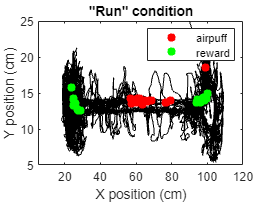

%Time indices for the run condition
idxcond = Nav.Condition == 3;

figure;

%plotting position of the animal
plot(Nav.X(idxcond), Nav.Y(idxcond), 'k');

%plotting positions of airpuffs 
hold on; a = scatter(Nav.X(idxcond & Nav.airpuff == 1), Nav.Y(idxcond & Nav.airpuff == 1), 'or', 'filled');

%plotting positions of rewards
hold on; r = scatter(Nav.X(idxcond & Nav.reward ~= 0), Nav.Y(idxcond & Nav.reward ~= 0), 'og', 'filled');

%adding legends and labels
legend([a, r], {'airpuff', 'reward'})
xlabel(gca, 'X position (cm)')
ylabel(gca, 'Y position (cm)')
title(gca, '"Run" condition')

%rescaling
set(gca,'Xlim', [5 120], 'Ylim', [5 25])
set(gca,'Xlim', [5 120])

**2.2. Computing the average speed across positions**

Hippocampal cells are selective to positions of the animal in the environment but they are also modulated by many other behavioral variables. In particular speed srtongly influences hippocamapal firing rates. Thus, if we want to understand the relationship between spatial coding and behavioral conditions, it is imperative that we have a clear picture of the relationship of latent variables such as speed with positions.

In this part, we want to compute the average speed across positions on the track. This method is important as we will basically use the same code to compute place field maps or any other analysis that involves averaging values in a variable as a function of another.

We will first compute this speed profile on the "run" condition, when the animal is going from the left to the right platform.

%Time indices for the run condition
tidx = Nav.Condition == 3 & Nav.laptype == 1 & ~isnan(Nav.Xpos) & ~isnan(Nav.Spd);

%Bin edges used to discretize Xpos
Xbinedges = 0:2:100;

%Number of bins
nXbins = numel(Xbinedges) - 1;

%Discretizing and subsetting Xpos
Xpos_discrete = discretize(Nav.Xpos(tidx), Xbinedges);

%Subsetting Nav.Spd
Spd = Nav.Spd(tidx);

%Summing speeds within indices of Xpos_discrete.
summap = sparse(ones(size(Xpos_discrete)), Xpos_discrete, Spd, 1, nXbins);
summap = full(summap);

%Summing occurences for each bin of Xpos_discrete.
occmap = sparse(ones(size(Xpos_discrete)), Xpos_discrete, ones(size(Spd)), 1, nXbins);
occmap = full(occmap);

%Smoothing summap and occmap with a Gaussian of s.d. of 1 bin
XsmthNbins = 1;
npts= 5;
x = (-(npts * XsmthNbins):(npts * XsmthNbins));
Smoother = exp(-x.^2 / XsmthNbins^2 /2);
summap = convn(summap,Smoother,'same');
occmap = convn(occmap,Smoother,'same');

%Calculating the average speed within each position bin by 
%dividing summap with occmap.
spdmap = summap ./ occmap;

The code above can be run by calling successively** Compute1DMap.m** and **GaussianSmooth1D.m**. 

Use these functions to compute the speed profile across positions for the pre-ru, the run and the post-run conditions, sorting left and right trials.

Xbinsize = 2;
Xbinedges = 0:Xbinsize:100;
nXbins = numel(Xbinedges) - 1;
XsmthNbins = 1;

%Discretizing positions
Xpos_discrete = discretize(Nav.Xpos, Xbinedges);

%Conditions to analyze
condList = [1 3 5];

%laptype to analyze
lapList = [-1 1];

%Iinitializing the final array
spdmap = NaN(nXbins, numel(lapList), numel(condList));

for icond = 1:numel(condList)
    for ilap = 1:numel(lapList)
        %Time indices for the current condition and laptype
        tidx =  Nav.Condition == condList(icond) & Nav.laptype == lapList(ilap) & ~isnan(Nav.Xpos) & ~isnan(Nav.Spd);

        %Quick note:laptype is non-zero onlywhen the animal don't make
        %U-turns. However, in this case, it did a lot of u-turns on the run
        %condition. making the overall speed slower than in the other
        %condition actually
        
        %Computing the sum of speeds within indices of Xpos_discrete.
        summap = Compute1DMap(Xpos_discrete(tidx), Nav.Spd(tidx), nXbins);

        %Smoothing the sum
        summap = GaussianSmooth1D(summap, XsmthNbins);

        %Computing the occupancy within each bin of Xpos_discrete.
        occmap = Compute1DMap(Xpos_discrete(tidx), ones(size(Nav.Spd(tidx))), nXbins);

        %Smoothing the occupancy
        occmap = GaussianSmooth1D(occmap, XsmthNbins);
        
        %Calculating the average speed
        spdmap(:,ilap, icond) = summap ./ occmap;
    end
end

Compare the speed profiles across positions between conditions and type of trials (L to R or R to L).

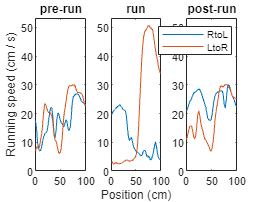

figure;

%Bin centers
Xbincenters = Xbinedges(1:end-1) + Xbinsize / 2;

%Number of condition analyzed
ncond = size(spdmap, 3);

%Maximium across all speeds for scaling purposes
m = 1.05 * max(spdmap(:));

%Condition labels for titling
condlabel = {'pre-run', 'run', 'post-run'};

%Plotting conditions and type of trials in different subplots
for icond = 1:ncond
    subplot(1,ncond,icond);
    
    %plotting
    plot(Xbincenters, spdmap(:,:,icond));
    set(gca, 'Ylim', [0 m]);
    
    %title, label and legend
    title(condlabel{icond})
    if icond == 1
        ylabel('Running speed (cm / s)')
    end
    if icond == 2
        xlabel('Position (cm)');
    end
    if icond == 3
        legend({'RtoL','LtoR'});
    end
end

**2.3. Computing air puff-triggered averages of speed**

We want to understand a bit more how the air puffs influence the speed of the animal. One way to understand the connection between a continuous variable and a discrete set of events is by computing an event-trigerred average. This approach will allow us to determine whether a discernible pattern exists in the average speed of the rat (across all trials) in relation to the timing of airpuff application. It will also allow us to look in more details at what happed on a trial by trial basis.

Compute the air-puff triggered average of the animal's speed over a window of 2 seconds centered on the air puff events.

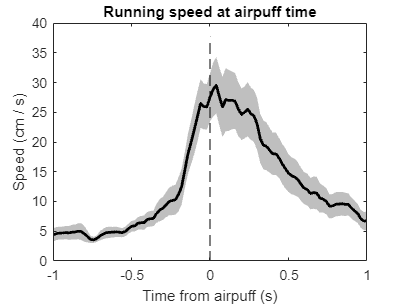

Spd = Nav.Spd(:);

%time indices where airpuffs are delivered
t = find(diff(Nav.airpuff) == 1) + 1;

%window of indices over which snippets will be extracted (-1 to 1 sec 
%around air puff time)
idxwin = (-1 * loadparams.sampleRate):(1 * loadparams.sampleRate);

%Padding Spd
idxmax = max(abs(idxwin));
Spd = [NaN(idxmax,1) ; Spd; NaN(idxmax,1)];

%Extracting snippets of Spd around timestamps in t
spdsnip = arrayfun(@(x) Spd(x + idxwin), t + idxmax, 'UniformOutput', false);
spdsnip = cat(2, spdsnip{:})';

%Average across snippets
spdAirpuff_ave = mean(spdsnip, 1, 'omitnan');

%S.E. across snippets
spdAirpuff_se = std(spdsnip, 0, 1, 'omitnan') ./ sqrt(size(spdsnip, 1));

%Plotting the result.
figure;
%Plot shaded area between lower and upper bounds.
ciplot(idxwin / loadparams.sampleRate, spdAirpuff_ave - spdAirpuff_se, spdAirpuff_ave + spdAirpuff_se);

%Plotting the line
hold on;plot(idxwin / loadparams.sampleRate, spdAirpuff_ave, 'k', 'linewidth', 2);

%scaling
m = max(spdAirpuff_ave + spdAirpuff_se, [], 'all');
hold on;plot([0 0], [0 1.1*m], 'k--');

%Labels and title
xlabel('Time from airpuff (s)')
ylabel('Speed (cm / s)')
title('Running speed at airpuff time')

The event-triggered average procedure above can be done by calling **ComputeTriggeredAverage.m **

Now, instead of looking at the average speed around air puffs in time, we would actually like to plot the average speed as a function of positions centered on the position where the air puff was delivered. This will allow us to see if things are consistent with the triggered average computed in the time domain.

**Hint**: one way to do that is by extracting the speed and positions snippets around air puff times before computing the spatial profile of speeds across positions from those snippets (after centering positions on the air puff position).

%First extract the snippet of speed around air puff times, just like above
Spd = Nav.Spd(:);

%time indices where airpuffs are delivered
t = find(diff(Nav.airpuff) == 1) + 1;

%Extracting snippets of Spd around timestamps in t
idxwin = (-1 * loadparams.sampleRate):(1 * loadparams.sampleRate);
[~, ~, spdsnip] = ComputeTriggeredAverage(Spd, t, idxwin);

%Extracting snippets of Xpos around timestamps in t
[~, ~, Xpossnip] = ComputeTriggeredAverage(Nav.Xpos, t, idxwin);

%Centering positions on air puff position
puffpos = Xpossnip(:,idxwin == 0);
Xpossnip = Xpossnip - puffpos;

%Extracting snippets of XDir around timestamps in t
[~, ~, XDirsnip] = ComputeTriggeredAverage(Nav.XDir, t, idxwin);

%Removing positions and speeds which are not in the direction of travel
%when the airpuff occurs
airpuffdir = 1;
Xpossnip(XDirsnip ~= airpuffdir) = NaN;
spdsnip(XDirsnip ~= airpuffdir) = NaN;

%Now we can compute the average speed as a function of positions, which are
%now aligned on the position of the air puffs.

%The dimension of the snippets don't really matter since we are interested
%in how one is related to the other. So let's reshape them as coloumn
%vectors for simplicity.
Xpossnip = Xpossnip(:);
spdsnip = spdsnip(:);

%Discretizing Xpossnip
binsize = 1;
binedges = -50:binsize:50;
nbins = numel(binedges) - 1;
smthNbins = 1;
Xpos_discrete = discretize(Xpossnip, binedges);

%Computing the occupancy in each position bin
occmap = Compute1DMap(Xpos_discrete, ones(size(spdsnip)), nbins);

%Thresholding the occupancy before smoothin to make sure we don't get
%artifactual values where there were actually not enough data
occmap(occmap < 1) = NaN;
occmap = GaussianSmooth1D(occmap, smthNbins);

%Computing the sum of speeds in each position bin
summap = Compute1DMap(Xpos_discrete, spdsnip, nbins);

%Smoothing after removing values in positions with too few points
summap(isnan(occmap)) = NaN;
summap = GaussianSmooth1D(summap, smthNbins);

%Voila. Average speed across positions centered on air puffs.
XspdAirpuff_run = summap ./ occmap;

Let's quickly do the same for the pre-run and the post-run conditions so we can compare the speed profile across conditions.

%Mean position of air puffs in the run condition
meanpuffpos = nanmean(puffpos);

condList = [1 5];
idxwin = (-1 * loadparams.sampleRate):(1 * loadparams.sampleRate);
binsize = 1;
binedges = -50:binsize:50;
nbins = numel(binedges) - 1;
smthNbins = 1;

for icond = 1:numel(condList)
    %time indices where airpuffs are delivered
    t = find(diff(sign(Nav.Xpos - meanpuffpos)) > 0 & Nav.Condition(1:end-1) == condList(icond));
    
    %Extracting snippets of Spd around timestamps in t
    [~, ~, spdsnip] = ComputeTriggeredAverage(Nav.Spd, t, idxwin);
    
    %Extracting snippets of Xpos around timestamps in t
    [~, ~, Xpossnip] = ComputeTriggeredAverage(Nav.Xpos, t, idxwin);
    
    %Centering positions on air puff position
    puffpos = Xpossnip(:,idxwin == 0);
    Xpossnip = Xpossnip - puffpos;
    
    %Extracting snippets of XDir around timestamps in t
    [~, ~, XDirsnip] = ComputeTriggeredAverage(Nav.XDir, t, idxwin);
    
    %Removing positions and speeds which are not in the direction of travel
    %when the airpuff occurs
    airpuffdir = 1;
    Xpossnip(XDirsnip ~= airpuffdir) = NaN;
    spdsnip(XDirsnip ~= airpuffdir) = NaN;
    
    Xpossnip = Xpossnip(:);
    spdsnip = spdsnip(:);
    
    %Discretizing Xpossnip
    Xpos_discrete = discretize(Xpossnip, binedges);
    
    %Computing the average of speed across positions
    occmap = Compute1DMap(Xpos_discrete, ones(size(spdsnip)), nbins);
    occmap(occmap < 1) = NaN;
    occmap = GaussianSmooth1D(occmap, smthNbins);
    summap = Compute1DMap(Xpos_discrete, spdsnip, nbins);
    summap(isnan(occmap)) = NaN;
    summap = GaussianSmooth1D(summap, smthNbins);
    
    if condList(icond) == 1
        XspdAirpuff_pre = summap ./ occmap;
    elseif condList(icond) == 5
        XspdAirpuff_post = summap ./ occmap;
    end
end

Plot the speed profiles triggered on air puff position for all three conditions

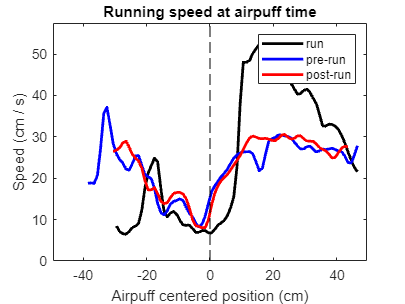

%bin centers for the X axes
bincenters = binedges(1:end-1) + binsize / 2;

figure;
%Plotting the speed profiles.
plot(bincenters, XspdAirpuff_run, 'k', 'linewidth', 2);
hold on;plot(bincenters, XspdAirpuff_pre, 'b', 'linewidth', 2);
hold on;plot(bincenters, XspdAirpuff_post, 'r', 'linewidth', 2);

%scaling
m = max([XspdAirpuff_run XspdAirpuff_pre XspdAirpuff_post]);
hold on;plot([0 0], [0 1.1*m], 'k--');
set(gca,'Ylim', [0 1.1*m],'Xlim', [bincenters(1) bincenters(end)]);

%Labels, legend and title
xlabel('Airpuff centered position (cm)')
ylabel('Speed (cm / s)')
legend({'run', 'pre-run', 'post-run'})
title('Running speed at airpuff time')

## **2. Matching spike times to behavioral data**

Spikes are typically recorded with a higher sampling frequency than behavioral data. To correlate spikes with behavior we generate spiking samples (i.e. firing rate values) at the same sampling frequency as the behavioral data.

#### 2.1. Load the spike times and the cluster info files.

%loading spike times and cluster ID in spk.HippoSpikes, a ntimes x 2 array
%containing spike times and clusters IDs.
spk = load([loadparams.Datafolder filesep loadparams.spkfilename]);

%loading information about clusters in spkinfo.IndexType, a ncells x 6
%array with the following information as columns: Rat, Session Number, 
%shank number, neuron, neuronID and celltype (1 for Pyramidal, 2 for
%interneuron)
spkinfo = load([loadparams.Datafolder filesep loadparams.spkinfofilename]);

#### 2.2. Match spike sampling frequency with behavioral data. 

All the spiking data will stored in a matlab structure (**Spk**), with different fields corresponding to different information about each cluster. 

Copy the previously loaded spike times and cluster ID into the Spk structure by converting it to an array of spike trains, sampled at the same sampling rate as the behavioral data.

The timestamps of the behavioral data and the spike recording have already been aligned together.

%Removing spikes that are before or after behavior started
extraspk = spk.HippoSpikes(:,1) < Nav.sampleTimes(1) | spk.HippoSpikes(:,1) > Nav.sampleTimes(end);
spk.HippoSpikes(extraspk,:) = [];

%Saving spike times and cluster IDs into Spk.spikeTimes and Spk.spikeID
Spk.spikeTimes = spk.HippoSpikes(:,1);
Spk.spikeID = spk.HippoSpikes(:,2);

%convert spike times into an array of spike trains, at the same resolution
%as the behavioral data.

%list of clusters IDs
clustList = unique(spk.HippoSpikes(:,2));

%number of clusters
ncells = max(clustList);

%number of time bins in the final spike train
nTimeSamples = numel(Nav.sampleTimes);

%Initializing Spk.spikeTrain
Spk.spikeTrain = zeros(nTimeSamples, ncells);

%Time bin edges to resample spike times
binEdges = [Nav.sampleTimes ; max(Nav.sampleTimes) + 1/loadparams.sampleRate];

%Spike times resampled for each cell
for icell = clustList(:)'
    s = spk.HippoSpikes(spk.HippoSpikes(:,2) == icell,1);
    Spk.spikeTrain(:,icell) = histcounts(s, binEdges);
end

%Final timestamps of the spike trains
Spk.sampleTimes = Nav.sampleTimes;

#### 2.3. Visualizing the activity of neurons as raster plots

Load the putative nature of the hippocampal clusters (i.e. pyramidal or interneuron)

%Indices of the clusters recorded in the hippocampus
HippoClustidx = ismember(spkinfo.IndexType(:,3), loadparams.ShankList);

%ShankID of each cluster
Spk.shankID = spkinfo.IndexType(HippoClustidx,3)';

%True if the cluster is a putative pyramidal cell
Spk.PyrCell = (spkinfo.IndexType(HippoClustidx,6) == 1)';

%True if the cluster is a putative interneuron
Spk.IntCell = (spkinfo.IndexType(HippoClustidx,6) == 2)';

Raster plot of all neurons together with the position of the animal over the first 100 seconds.

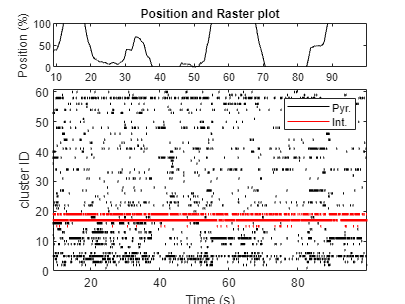

%time window over which to display the raster plot
timewin = [0 100];

%height of the ticks for each spike (between 0 and 1)
spkheight = 0.4;

%Time indices corresponding to the requested time window
tidx = Nav.sampleTimes >= timewin(1) & Nav.sampleTimes <= timewin(2);

figure;

%Plotting the position of the animal on the track
subplot(4,1,1);
plot(Nav.sampleTimes(tidx), Nav.Xpos(tidx), 'k')

%finding the spike times and the cell IDs for each spikes
t = Nav.sampleTimes(tidx);
[spkidx, cellidx] = find(Spk.spikeTrain(tidx,:) > 0);
xpoints = t(spkidx);
ypoints = cellidx;

%Alternatively, one could use the Spk.spikeTimes instead of 
%finding spike times from the spike trains.
% spkidx = Spk.spikeTimes >= timewin(1) & Spk.spikeTimes <= timewin(2);
% xpoints = Spk.spikeTimes(spkidx);
% ypoints = Spk.spikeID(spkidx);

%Plotting spikes as vertical lines at a height defined by the clusterID
subplot(4,1,[2 3 4]);
p1 = plot([xpoints xpoints]', [ypoints - spkheight ypoints + spkheight]', 'k');

%Overlaying spikes of interneurons in a different color
intspkidx = Spk.IntCell(ypoints);
xpointsInt = xpoints(intspkidx);
ypointsInt = ypoints(intspkidx);
subplot(4,1,[2 3 4]);
hold on;
p2 = plot([xpointsInt xpointsInt]', [ypointsInt - spkheight ypointsInt + spkheight]', 'r');

%Scales, labels, legend etc...
subplot(4,1,1);
set(gca,'Xlim', [min(t) max(t)], 'Ylim', [0 100])
ylabel('Position (%)')
title('Position and Raster plot')

subplot(4,1,[2 3 4]);
set(gca,'Xlim', [min(t) max(t)], 'Ylim', [0 size(Spk.spikeTrain, 2) + 1])
xlabel('Time (s)')
ylabel('cluster ID')
legend([p1(1), p2(1)], {'Pyr.', 'Int.'})

## 4. Visualizing the spatial selectivity of hippocampal place cells

Hippocampal neurons known as place cells fire in specific locations. But some hippocampal place cells are also influenced by movement direction, especially within a 1-D linear track. Certain cells exhibit unidirectional firing, i.e. selective to a position but exclusively during Left-to-Right movements. In contrast, some cells show bidirectional firing behaviors, which may or may not be with the same place preference. We want to illustrate the place selectivity of hippocampal place cells in our data and their selectivity to movement direction within a 1-D linear track. 

#### 4.1. Spatial selectivity and directionality of place cells

Plot the spikes of cells #1, #18 and #27 over the (X,Y) positions of the animal for conditions [1 3 5].

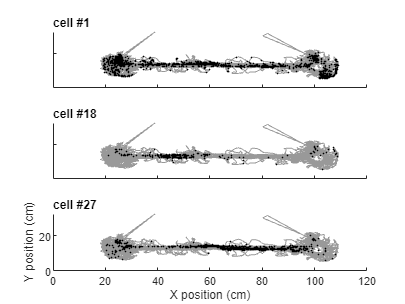

%Selecting time indices
tidx = ismember(Nav.Condition, [1 3 5]);

%List of cells to plot
cellList = [1 18 27]; 

figure;
for icell = 1:numel(cellList)
    %plotting the trajectory of the animal
    subplot(numel(cellList), 1, icell);
    plot(Nav.X(tidx), Nav.Y(tidx), 'Color', [0.6 0.6 0.6]);

    %plotting positions at spike times
    spkidx = Spk.spikeTrain(:,cellList(icell)) > 0;
    hold on; scatter(Nav.X(tidx & spkidx), Nav.Y(tidx & spkidx), 'o', 'filled', 'MarkerFaceColor','k','SizeData',1);
    
    %labels, title, etc
    if icell ~= numel(cellList)
        set(gca, 'XtickLabel', [], 'YtickLabel', []);
    else
        xlabel('X position (cm)')
        ylabel('Y position (cm)')
    end
    title(['cell #' num2str(cellList(icell))])
    set(gca,'box', 'off','TitleHorizontalAlignment','left')
end

Compute the response profiles of cells #1, #18 and #27 across X positions (**Nav.Xpos**) using **Compute1DMap.m **and **GaussianSmooth1D.m. **Do so seperately depending on the animal is moving in one direction or another (as estimated in **Nav.XDir**).

%List of cells to plot
cellList = [1 18 27];
ncells = numel(cellList);

%Bins size, bin edges, and smoothing parameter for position
Xbinsize = 4;
Xbinedges = 0:Xbinsize:100;
nXbins = numel(Xbinedges) - 1;
XsmthNbins = 1;

%Discretizing positions
Xpos_discrete = discretize(Nav.Xpos, Xbinedges);

%Condition to analyze
condList = [1 3 5];

%Direction to analyze
dirList = [-1 1];

%Iinitializing the final array
mapXDir = NaN(ncells, nXbins, numel(dirList));


for idir = 1:numel(dirList)
    %Time indices for the current direction
    tidx =  ismember(Nav.Condition, condList) & Nav.XDir == dirList(idir) & ~isnan(Nav.Xpos);
    
    %Computing the occupancy within each bin of Xpos_discrete.
    flat = ones(size(Xpos_discrete(tidx))) / loadparams.sampleRate;
    occmap = Compute1DMap(Xpos_discrete(tidx), flat, nXbins);
    
    %Smoothing the occupancy
    occmap = GaussianSmooth1D(occmap, XsmthNbins);

    for icell = 1:ncells
        %Computing the spike count map within indices of Xpos_discrete.
        scmap = Compute1DMap(Xpos_discrete(tidx), Spk.spikeTrain(tidx,cellList(icell)), nXbins);

        %Smoothing the spike count map
        scmap = GaussianSmooth1D(scmap, XsmthNbins);

        %Calculating the response spatial profile
        mapXDir(icell,:,idir) = scmap ./ occmap;
    end
end

Plot the response profiles along X for those three cells

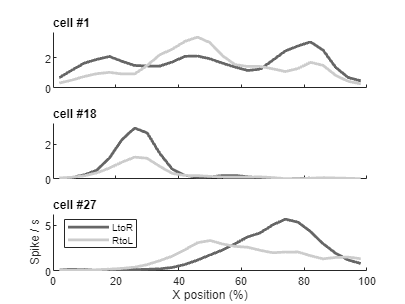

%IDs of cells in mapXDir
cellnum = [1 18 27]; 

%Bin centers
Xbincenters = Xbinedges(1:end-1) + Xbinsize / 2;

figure;
for icell = 1:size(mapXDir, 1)
    %plotting the response profiles for both directions
    subplot(numel(cellList), 1, icell);
    plot(Xbincenters, squeeze(mapXDir(icell,:,1)), 'Color', [0.4 0.4 0.4], 'linewidth', 2);
    hold on;plot(Xbincenters, squeeze(mapXDir(icell,:,2)), 'Color', [0.8 0.8 0.8], 'linewidth', 2);
    
    %finding the maximium response for scaling purposes
    m = max(mapXDir(icell,:,:), [], 'all');
    set(gca, 'Ylim', [0 1.1*m]);

    %labels, title, legend etc
    if icell ~= numel(cellList)
        set(gca, 'XtickLabel', []);
    else
        xlabel('X position (%)')
        ylabel('Spike / s')
        legend({'LtoR', 'RtoL'}, 'location', 'northwest')
    end
    title(['cell #' num2str(cellnum(icell))])
    set(gca,'box', 'off','TitleHorizontalAlignment','left')
end

#### 4.2. Spatial selectivity of place cells in 2D

Although recordings were performed on a linear track, we would sill like to visualize the response profile of place cells along both X and Y.

Compute the 2D reponse profile across X and Y positions (**Nav.X** and **Nav.Y**) for the same cells as above, using **Compute2DMap.m** and **GaussianSmooth.m **

cellList = [1 18 27];
ncells = numel(cellList);

%Paramters for discretizing X
Xbinsize = 2;
Xbinedges = 10:Xbinsize:110;
nXbins = numel(Xbinedges) - 1;
XsmthNbins = 2;

%Paramters for discretizing Y
Ybinsize = 0.5;
Ybinedges = 5:Ybinsize:25;
nYbins = numel(Ybinedges) - 1;
YsmthNbins = 0;

%Discretizing X and Y positions
X_discrete = discretize(Nav.X, Xbinedges);
Y_discrete = discretize(Nav.Y, Ybinedges);

%Conditions to analyze
condList = [1 3 5];

%Iinitializing the final array
mapXY = NaN(ncells, nYbins, nXbins);

%Time indices for the selected conditions
tidx =  ismember(Nav.Condition, condList);

%Computing the occupancy within each bin of X_discrete x Y_discrete.
flat = ones(size(X_discrete(tidx))) / loadparams.sampleRate;
occmap = Compute2DMap(X_discrete(tidx), Y_discrete(tidx), flat, nXbins, nYbins);

%Excluding all values where occupancy is below a threshold
occmap(occmap < 0.2) = NaN;

%Smoothing the occupancy
occmap = GaussianSmooth(occmap, [YsmthNbins XsmthNbins]);

for icell = 1:ncells
    %Computing the spike count map within indices of Xpos_discrete.
    scmap = Compute2DMap(X_discrete(tidx), Y_discrete(tidx), Spk.spikeTrain(tidx,cellList(icell)), nXbins, nYbins);
    
    %Excluding all values where occupancy is zero
    scmap(isnan(occmap)) = NaN;

    %Smoothing the spike count map
    scmap = GaussianSmooth(scmap, [YsmthNbins XsmthNbins]);

    %Calculating the response spatial profile
    mapXY(icell,:,:) = scmap ./ occmap;
end

Plot the corresponding spatial profiles as colored maps

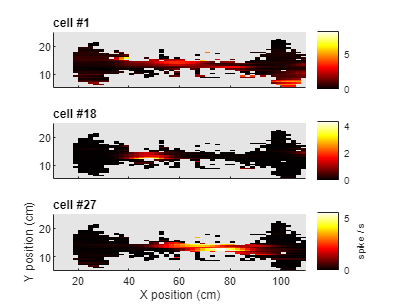

%Converting NaNs to inf so that it saturates when plotted
mapXY(isnan(mapXY)) = inf;

%IDs of cells in mapXDir
cellnum = [1 18 27]; 

%Bin centers
Xbincenters = Xbinedges(1:end-1) + Xbinsize / 2;
Ybincenters = Ybinedges(1:end-1) + Ybinsize / 2;

figure;
for icell = 1:size(mapXY, 1)
    %plotting the 2D response profiles
    subplot(numel(cellList), 1, icell);
    imagesc(Xbincenters, Ybincenters, squeeze(mapXY(icell,:,:)));
        
    %finding the maximium response for scaling purposes
    m = max(mapXY(icell,:,:), [], 'all');
    set(gca, 'Clim', [0 1.5*m]);

    %labels, title, legend etc
    c = colorbar;
    if icell ~= numel(cellList)
        set(gca, 'XtickLabel', []);
    else
        xlabel('X position (cm)')
        ylabel('Y position (cm)')
        c.Label.String = 'spike / s';
    end
    title(['cell #' num2str(cellnum(icell))])
    set(gca,'box', 'off','TitleHorizontalAlignment','left')
    set(gca,'Ydir', 'normal')
end

%making the saturating color (for inf values) different from the normal
%scale.
cmap = colormap(hot);
cmap(end,:) = [0.9 0.9 0.9];
colormap(cmap);